# Time evolution of the 1D problem

### 1D thermal evolution problem

The time evolution of the temparature, $u = u(t,x)$, along a bar of length $L$, thermal conductivity $k_{c}$, section area $A$, and heat generation $f(x)$, $0\le x\le L$, is given by the solution of the BVP

 
$$\qquad\qquad\quad a_{2}\frac{\partial u}{\partial t} - \frac{\partial}{\partial x}\left(a_{1}\frac{\partial u}{\partial x}\right)  = f(x), \qquad u(t,0) = u_{0}(t), \quad u(t,L) = u_{L}(t),\quad t\ge 0,$$


$a_{1} = a_{2} = k_{c} A$, provided its distribution at time $t=0$, $v_{0}(x)$, is also known; so that

$\qquad\qquad\quad u(0,x) = v_{0}(x),\qquad 0\le x\le L$.

In this context on refers to $v_{0}(x)$ as the *initial condition* of the BVP.

### Fixed temperature at the boundaries

Consider a bar of length $L = 1$, section area $A = 0.1$, and thermal conductivity $k_{c} = 2.5$ whose ends $x=0$ and $x=L$ are  kept at constant temperatures of $10^{\text{o}}$C and $60^{\text{o}}$C respectively. Assume also that no internal heat generation is present $(\text{i.e.,} f(x) = 0, 1\le x\le 1)$.

If the initial distribution of the temperature along the bar was 


$$\qquad\qquad\quad v_{0}(x) = 10 + 50\sin\left(\displaystyle\frac{\pi x}{2}\right).$$


Then, 

- Mesh the domain $\Omega = [0,1]$ with $m=500$ linear elements, and use the  FEM  to find the nodes' temperatures in a sample of equispaced time ticks from $t_{\text{ini}} = 0$ to $t_{\text{final}}=0.2$ (both included), separated by $\Delta t = 0.01$.

- Find the error between the temperature at the nodes at $t_{\text{final}} = 0.2$, $u(t_{\text{final}},x_{k})$, at the global nodes $k=1,2,\dots,n$, and the temperature at the same nodes, but for the stationary model, $u(x_{k}$). More precisely, if $u_{t_\text{final}}^{\top} := \left(u(t_{\text{final}},x_{1}),  u(t_{\text{final}},x_{2}),\dots, u(t_{\text{final}},x_{n})\right)$ and $u_{\text{stat}} := \left(u(x_{1}),u_{2}(x),\dots,u(x_{n})\right)$, compute $\epsilon:=\| u_{t_{\text{final}}}-u_{\text{stat}}\|$.

*Remark on notation: *in what follows, $m$ will be the number of elements $\Omega^{e}$; $N_{e}$ will denote the number of *local* nodes of element $\Omega^{e}$, $e=1,\dots,m$ and, finally, $n$ will stand for the number of *global* nodes. 

### Weak formulation

We mesh the domain $\Omega = [0, 1]$ into elements $\Omega^{e} =[x_{1}^{e}, x^{e}_{N_{e}}]$, where we place $N_{e}$ nodes at positions 


$$\qquad\qquad\quad x^{e}_{1} < x^{e}_{2} < \dots < x^{e}_{N_{e}},\, \text{ such that } x^{e}_{N_{e}} = x^{e+1}_{1}  \text{  for } e = 1,\dots, m-1, \text{ so } \Omega = \cup\limits_{j=1}^{m} \Omega^{e}.$$


The weak formulation on the elments $\Omega^{e}$ ($e = 1,\dots,m$) reads


$$\displaystyle(1)\qquad\qquad\int^{x^{e}_{1}}_{x^{e}_{N_{e}}} a_{2}\omega(x)\frac{\partial u}{\partial t}(t,x)\text{d} x 
+ \int_{x^{e}_{1}}^{x^{e}_{N_{e}}} a_{1} \frac{\text{d} \omega}{\text{d} x}(x)\frac{\partial u}{\partial x}(t,x)\text{d}x
\\
\qquad\qquad\qquad\qquad\qquad= a_{1}\omega(x^{e}_{N_{e}})\frac{\partial u}{\partial x}(t,x^{e}_{N_{e}})
- a_{1}\omega(x^{e}_{1})\frac{\partial u}{\partial x}(t,x^{e}_{1}) +
\int^{x^{e}_{N_{e}}}_{x^{e}_{1}} \omega(x) f(x)\text{d}x.$$


Next, we approximate the solution $u(t,x)$ on each element by the linear combination $\displaystyle (2)\qquad\qquad U^{e}(t,x) =
  \sum_{j=1}^{N_{e}} U^{e}_{j}(t)\,\psi_{j}^{e}(x)
  = U^{e}_{1}(t)\,\psi^{e}_{1}(x) + U^{e}_{2}(t)\,\psi^{e}_{2}(x) + \cdots
  + U^{e}_{N_{e}}(t)\,\psi^{e}_{N_{e}}(x)$

(recall that $\psi^{e}_{j}(x)$, $j=1,\dots,N_{e}$ are the shape functions of the element) and take$\omega(x) = \psi^{e}_{i}(x)$, $e=1,\dots,m$. With this choice of the test functions, substitution of $(2)$ into the infegral equation $(1)$ leads to a system of $N_{e}$ ordinary differential equations (ODEs) of $1^{\text{st}}$ order. Explicitly,


$$\displaystyle 
(3)\qquad\qquad
\sum\limits^{N_{e}}_{j=1}\left(\displaystyle\int_{x^{e}_{1}}^{x^{e}_{N_{e}}}
a_{2} \psi^{e}_{i}(x)\psi^{e}_{j}(x)\text{d} x\right)\,\dot{U}^{e}_{j}(t)
+\sum\limits^{N_{e}}_{j=1}\left(\displaystyle\int_{x^{e}_{1}}^{x^{e}_{N_{e}}}
a_{1} \frac{\text{d}\psi^{e}_{i}}{\text{d} x}(x)
\frac{\text{d} \psi^{e}_{j}}{\text{d} x}(x)\text{d} x\right)\,U^{e}_{j}(t)\\
\displaystyle
\qquad\qquad\qquad
\qquad\qquad\qquad = 
a_{1}\psi^{e}_{i}(x^{e}_{N_{e}})\frac{\partial u}{\partial x}(t,x^{e}_{N_{e}})
-a_{1}\psi^{e}_{i}(x^{e}_{1})\frac{\partial u}{\partial x}(t,x^{e}_{1}) 
+ \int_{x^{e}_{1}}^{x^{e}_{N_{e}}} \psi^{e}_{i}(x) f(x)\text{d} x,$$


$i=1,\dots,N_{e}$, ($e = 1,\dots, m$). We can re-write system $(3)$ in vector notation as,


$$(4)\qquad\qquad M^{e}\dot{U}^{e} + K^{e} U^{e} = F^{e} + Q^{e}$$


where $M^{e}$, $K^{e}$ are the *local* mass and the stiffnes matrces respectively whose components are given by,


$$\displaystyle
\qquad\qquad\quad M^{e}_{ij} =\displaystyle\int_{x^{e}_{1}}^{x^{e}_{N_{e}}}
             a_{2}\, \psi^{e}_{i}(x)\psi^{e}_{j}(x)\,\text{d} x,\quad
K^{e}_{ij} = \displaystyle\int_{x^{e}_{1}}^{x^{e}_{N_{e}}}
a_{1} \frac{\text{d}\psi^{e}_{i}}{\text{d} x}(x)
      \frac{\text{d}\psi^{e}_{j}}{\text{d} x}(x)\text{d}x,\quad
i,j = 1,\dots,N_{e}$$


whereas the components of the local vectors $F^{e}$ and $Q^{e}$ are


$$(5) \qquad\qquad
\left\{
\begin{array}{l}   
   F^{e}_{i} = \displaystyle\int_{x^{e}_{1}}^{x^{e}_{N_{e}}}
                \psi^{e}_{i}(x) f(x)\text{d} x,\\
   Q^{e}_{i} = \displaystyle a_{1}\psi^{e}_{i}(x^{e}_{N_{e}})
               \frac{\partial u}{\partial x}(t,x^{e}_{N_{e}})
               - a_{1}\psi^{e}_{i}(x^{e}_{1})
               \frac{\partial u}{\partial x}(t,x^{e}_{1})
               = a_{1}\delta_{N_{e} i}
               \frac{\partial u}{\partial x}(t,x^{e}_{N_{e}})
               - a_{1}\delta_{1 i}
               \frac{\partial u}{\partial x}(t,x^{e}_{1}),
\end{array}
\right.$$


for $i = 1,\dots,N_{e}$.

### Assembly

The assembly of local mass and stiffness matrices $M^{e}$, $K^{e}$ and of the vectors $F^{e}$ and $Q^{e}$ carries out exactly as in the stationary case (see the code below).

Let,

- $M$ be the global mass matrix, as obtained from assembling the local mass matrices $M^{e}$, $e = 1,\dots,m$

- $K$ be the global stiffness matrix, as obtained from assembling the local matrices $K^{e}$, $e = 1,\dots,m$

- $F$, $Q$ be the global vector that results from the assembling the local vectors $F^{e}$ and local $Q^{e}$, $e = 1,\dots,m$.

Then the global system

    
$$\qquad\qquad M\dot{u} + K u = F + Q,$$


is a system of $n$ linear ODEs of $1^{\text{st}}$ order, where $n$ is the number of *global *nodes, and the $i^{\text{th}}$component of its solution, $u_{i}(t)$, gives the temperature of the $i^{\text{th}}$ node at time $t$, for each $i = 1,\dots,n$.

### Boundary conditions. Reduced system

In this case in point, from the BC of the given BVP, it follows, on the one hand, that

    
$$\qquad\qquad u_{1}(t) = 10,\quad u_{n}(t) = 60,$$


for all $t \ge 0$; so, consequently, $\dot{u}_{1}(t) = 0$, and $\dot{u}_{n}(t) = 0$. On the other hand, from (5) it follows that $Q^{e}_{j} = 0$ for $e=1,\dots,m$,$j=2,\dots,N_{e}-1$;  and that $Q^{e}_{N_{e}} + Q^{e+1}_{1} = 0$ for all $e = 1,\dots, m-1$. Therefore $Q_{i}$ = 0 for $i=2,\dots,n-1$, so the *reduced system* casts


$$\qquad
\begin{array}{rcl}
\left(\begin{array}{cccc}
  M_{2,2} & M_{2,3} & \cdots & M_{2,n-1}\\
  M_{3,2} & M_{3,3} & \cdots & M_{3,n-1}\\
  \vdots  & \vdots  & \ddots & \vdots \\
  M_{n-1,2} & M_{n-1,3} & \cdots & M_{n-1,n-1}
\end{array}\right)
\left(\begin{array}{c}
\dot{u}_{2}\\
\dot{u}_{3}\\
\vdots\\
\dot{u}_{n-1}\\
\end{array}\right)
&+&
\left(\begin{array}{cccc}
  K_{2,2} & K_{2,3} & \cdots & K_{2,n-1}\\
  K_{3,2} & K_{3,3} & \cdots & K_{3,n-1}\\
  \vdots  & \vdots  & \ddots & \vdots \\
  K_{n-1,2} & K_{n-1,3} & \cdots & K_{n-1,n-1}
\end{array}\right)
\left(\begin{array}{c}
u_{2}\\
u_{3}\\
\vdots\\
u_{n-1}
\end{array}\right) 
\\ 
  &=& 
\left(\begin{array}{c}
F_{2}\\
F_{3}\\
\vdots\\
F_{n-1}
\end{array}\right) + 
\left(\begin{array}{c}
0\\
0\\
\vdots\\
0
\end{array}\right) -
u_{1}(t) 
\left(\begin{array}{c}
K_{2,1}\\
K_{3,1}\\
\vdots\\
K_{n-1,1}
\end{array}\right) - 
u_{n}(t) 
\left(\begin{array}{c}
K_{2,n}\\
K_{3,n}\\
\vdots\\
K_{n-1,n}
\end{array}\right)-
\dot{u}_{1}(t)
\left(\begin{array}{c}
M_{2,1}\\
M_{3,1}\\
\vdots\\
M_{n-1,1}
\end{array}\right) - 
\dot{u}_{n}(t) 
\left(\begin{array}{c}
M_{2,n}\\
M_{3,n}\\
\vdots\\
M_{n-1,n}
\end{array}\right)
\end{array}
\end{array}$$


or, in vector notation,


$$\displaystyle (6)\qquad\qquad \tilde{M}\dot{U} + \tilde{K} U = \tilde{F}, $$


being


$$\qquad\qquad\quad
U(t) := \left(\begin{array}{c}
u_{2}(t)\\
u_{3}(t)\\
\vdots\\
u_{n-1}(t)\end{array}\right),\qquad

\tilde{M} := 
\left(\begin{array}{cccc}
  M_{2,2} & M_{2,3} & \cdots & M_{2,n-1}\\
  M_{3,2} & M_{3,3} & \cdots & M_{3,n-1}\\
  \vdots  & \vdots  & \ddots & \vdots \\
  M_{n-1,2} & M_{n-1,3} & \cdots & M_{n-1,n-1}
\end{array}\right),\qquad
\tilde{K} := \left(\begin{array}{cccc}
  K_{2,2} & K_{2,3} & \cdots & K_{2,n-1}\\
  K_{3,2} & K_{3,3} & \cdots & K_{3,n-1}\\
  \vdots  & \vdots  & \ddots & \vdots \\
  K_{n-1,2} & K_{n-1,3} & \cdots & K_{n-1,n-1}
\end{array}\right),$$


and


$$\qquad\qquad\quad \tilde{F}(t):=\left(\begin{array}{c}
F_{2}\\
F_{3}\\
\vdots\\
F_{n-1}
\end{array}\right) + 
\left(\begin{array}{c}
0\\
0\\
\vdots\\
0
\end{array}\right) -
u_{1}(t) 
\left(\begin{array}{c}
K_{2,1}\\
K_{3,1}\\
\vdots\\
K_{n-1,1}
\end{array}\right) - 
u_{n}(t) 
\left(\begin{array}{c}
K_{2,n}\\
K_{3,n}\\
\vdots\\
K_{n-1,n}
\end{array}\right)-
\dot{u}_{1}(t)
\left(\begin{array}{c}
M_{2,1}\\
M_{3,1}\\
\vdots\\
M_{n-1,1}
\end{array}\right) - 
\dot{u}_{n}(t) 
\left(\begin{array}{c}
M_{2,n}\\
M_{3,n}\\
\vdots\\
M_{n-1,n}
\end{array}\right)
\end{array}$$


*Remark*: recall that in the current example, the temperatures are fixed at the boundaries: $u_{1}(t)$=10 and $u_{n}(t) = 60$, so $\dot{u}_{1}(t) = \dot{u}_{n}(t) = 0$ for all $t\ge 0$. Therefore, on the one hand,


$$\qquad\qquad\quad \tilde{F}:=\left(\begin{array}{c}
F_{2}\\
F_{3}\\
\vdots\\
F_{n-1}
\end{array}\right) + 
\left(\begin{array}{c}
0\\
0\\
\vdots\\
0
\end{array}\right) -
10 
\left(\begin{array}{c}
K_{2,1}\\
K_{3,1}\\
\vdots\\
K_{n-1,1}
\end{array}\right) - 
60 
\left(\begin{array}{c}
K_{2,n}\\
K_{3,n}\\
\vdots\\
K_{n-1,n}
\end{array}\right)$$


so $\tilde{F}$does not depend on $t$ and, on the other hand, neither $\tilde{M}$ nor $\tilde{K}$ do, for none of the coefficients $a_{1}$ or $a_{2}$ depend on $t$ (actually they are constants). All what follows is derived for this particular case.

### Numerical solution of ODEs

The idea is to approximate the difference $U(t+\Delta t) - U(t)$ by,


$$(7)\qquad\qquad U(t+\Delta t) - U(t) = \alpha \Delta t\, \dot{U}(t+\Delta t) + (1-\alpha)\Delta t\,\dot{U}(t).$$


For different values of $\alpha$ this yields different numerical methods. Most common are:

- For $\alpha = 0$, the method of *Forward Differences, *which is conditionally stable and $\mathcal{O}(\Delta t)$.

- For $\alpha = 1/2$, the method of *Crank-Nicholson, *which is stable and $\mathcal{O}(\Delta t^{2})$.

- For $\alpha = 2/3$, the method of *Galerkin, *which is stable and $\mathcal{O}(\Delta t^{2})$.

- For $\alpha = 1$ the method of *Backward Differences, *which is stable and $\mathcal{O}(\Delta t)$

We can solve (6) recursively. Indeed; First, multiply the equation (7) by $\tilde{M}$ to get:


$$(8)\qquad\qquad\tilde{M} U(t+\Delta t) -\tilde{M} U(t) = \alpha \Delta t\,\tilde{M} \dot{U}(t+\Delta t) + (1-\alpha)\Delta t\,\tilde{M}\dot{U}(t).\qquad\qquad\qquad$$


Second,  evaluate (6) in $t+\Delta t$ and in $t$, we mean,


$$\qquad\qquad
\begin{array}{rcl}
\tilde{M} \dot{U}(t+\Delta t)\!\!\!\! &=&\!\!\!\tilde{F} - \tilde{K} U(t+\Delta t),\\
\tilde{M} \dot{U}(t)\!\!\! &=&\!\!\! \tilde{F} - \tilde{K} U(t).
\end{array}$$


 Finally, substitute in the r.h.s. of (8)  and solve in $U(t+\Delta t)$, which leads to$(9)\qquad\quad \left(\tilde{M} + \alpha\Delta t\tilde{K}\right)U(t+\Delta t) = \left(\tilde{M} - (1-\alpha)\Delta t \tilde{K}\right) U(t) + \Delta t \tilde{F}$

Using (9) we can approximate the temperature at time $t+\Delta t$, provided we know the temperatue at time $t$. Hence, if the initial value of U is known at $t=t_{\text{ini}}$, we can find the approximate solution at each of the nodes $x_{2},\dots,x_{n-1}$, i.e.,


$$u_{1}(t_{i}) = u_{0},\quad U(t_{i}) = \left(u_{2}(t_{i}),\dots,u_{n-1}(t_{i})\right)^{\top},\quad u_{n}(t_{i}) = u_{L}$$


 at times $t_{i} = t_{1} + i\Delta t$, $i=2,\dots,m$, with $t_{m} = t_{\text{final}}$. 

**Remark. **Note that in our example, at $x_{1} = 0$, $u(t,0) = u_{0} = 10\,\left( = v_{0}(0)\right)$ and, at $x_{n} = L = 1$, $u(t,1)=$$u_{L} = 60$ $\, \left( = v_{0}(1)\right)$ for all $t\in [t_{i},t_{f}] =$$[0,t_{f}]$ = $[0,0.2]$, so we have


$$u_{1}(t_{i}) = u_{0} = 10,\quad\quad u_{n}(t_{i}) = u_{L} = 60$$


for all $i = 1,\dots,m$.

### Scheme for the solution of LODE (6)

Let us consider a mesh of the interval $\Omega = [0,L]$ given by the $n$ nodes, $x_{k} = x_{k} + (k-1) h$, $k=1,\dots,n$, with$x_{1} = 0$, $x_{n} = L$, and $n-1$ linear elements  the same length $h = L/(n-1)$. Besides, we take $m$ time-ticks separated by a constant leap $\Delta t$, i.e., $t_{i} = t_{1} + i\Delta t$, $i=1,\dots,m$, with $t_{1}=t_{\text{ini}} = 0$, and $t_{m}=t_{\text{final}}$ $= 0.2.$In addition we detine


$$V_{0} = \left(v_{0}(x_{2}), v_{0}(x_{2}),\dots,v_{0}(x_{n-1})\right)^{\top$$


**Remark. **Note that in our example $v_{0}(0) = u(t,0) = u_{0} = 10$ and $v_{0}(1) = u(t,1) = u_{L} = 60$ for all $t\in [t_{i},t_{f}] =$$[0,t_{f}]$ = $[0,0.2]$, so, in particular $u_{1}(t) = 10$ and $u_{n}(t) = 60$ in the same interval.   

Therefore, the nodal solution at every time-tick $t_{i}$, $i=2,\dots,m-2$ is given, recursively, by the algorithm


$$\begin{array}{rcl}
     U(t_{1}) &\!\!\!\!\!\!\!=\!\!\!\!\!& V_{0},\\
  U(t_{i+1}) &\!\!\!\!\!\!\!=\!\!\!\!\!& \left(\tilde{M} + \alpha\Delta t\tilde{K}\right)^{-1}\left[\left(\tilde{M} - (1-\alpha)\Delta t\tilde{K}\right)U(t_{i}) + \Delta t \tilde{F}\right], \qquad i = 2,\dots, m-1,
\end{array}$$


 Which allows us to know $U(t_{i}) = \left(u_{2}(t_{i}),\dots,u_{n-1}(t_{i})\right)^{\top}$at each time-tick $t_{i}$, for $i=1,\dots,m$, whereas for the notes at $x_{1} = 0$, $x_{n} = L$, we have $u_{1}(t_{i}) = u(t_{i},0) = u_{0} = 10$, and $u_{n}(t_{i}) = u(1,t_{i}) = u_{L} = 60$ for all $i=1,\dots,m$ (see the Remark at the end of the previous section). In this way we've found the nodal solution 


$$u_{1}(t_{i}), u_{2}(t_{i}),\dots,u_{n}(t_{i})$$


for each time tick $t_{i} = t_{1} + i\Delta t$, $i=1,\dots,m$, with $t_{1} = t_{\text{ini}}$, and $t_{m} = t_{\text{final}}$.

### Let's begin to write code!

clearvars 
close all

%Physical constants
kc = 2.5;
A = 0.1;

%Boundary conditions
uA = 10;
uB = 60;

%Initial condition
u_ini = @(x) 10 + 50*sin(pi*x/2);

%FEM: geometry
a = 0; b = 1; numDiv = 500;
h = (b-a)/numDiv;

tini = 0;
tfin = 0.2;
dt = 0.01;
%t = tini:dt:tfin; %Time ticks where the (apprximate) solution is computed
alpha = 0.5;       %Crank-Nicolson (CN)

a1 = kc*A;
a2 = a1;

nodes = (a:h:b)'; %nodes
elem = [1:numDiv; 2:numDiv+1]'; %connectivity natrix: linear elements

numNod = size(nodes,1);   %find out number of nodes
numElem = size(elem, 1);  %find out number of elements

#### Local stiff matrices and load vector

We shall use *linear elements *and the functions $a_{1}(x)\equiv a_{1}^{e}$, $a_{2}(x)\equiv a_{2}^{e}$, and $f(x) \equiv f^{e}$ will be constants on each element. (actually for the current example, their values are goint to be the same through all the elements), the corresponding local matrices  and load vector are


$$(10)\qquad\qquad\quad M^{e} = \frac{a_{2}^{e} h_{e}}{2}\left(\begin{array}{rr}
2 & 1\\
1 & 2
\end{array}\right),\qquad
K^{e} = \frac{a_{1}^{e}}{h_{e}}\left(\begin{array}{rr}
1 & -1\\
-1 & 1
\end{array}\right),\qquad
F^{e} = \frac{f^{e}h_{e}}{2}\left(\begin{array}{r}
1\\
1
\end{array}\right),$$


note, in particuar that the matrix $M^{e}$ coincides with the matrix $K^{e,0}$ that appears in the notes for the same case of linear elements with constant coefficients, if we change the coefficent $a^{e}_{2}$ by the coefficient $a^{e}_{0}$. This last point becomes evident if we look at the integrals that give their components.

Actually, in the current example, the values of $a_{1}^{e}$, $a_{2}^{e}$ and $f^{e}$are going to be the same for all the elements, we write $a_{1} = a_{1}^{e}$, $a_{e} = a_{2}^{e}$, $f = f^{e}$. The particular values for this case in point are $a_{1} = a_{2} = k_{c} A$, with $A = 0.1$, $k_{c} = 2.5$, and $f = 0$. 

#### **Some remarks**

First, we recall that, for quadratic elements, the local stiff matrices and the load vector are: 


$$M^{e} = \frac{a^{e}_{2} h_{e}}{30}\left(\begin{array}{rrr}
4 & 2 & -1\\
2 & 16 & 2\\
-1 & 2 & 4
\end{array}
\right),\qquad
K^{e} = \frac{a^{e}_{1}}{3 h_{e}}\left(
\begin{array}{rrr}
7 & -8 & 1\\
-8 & 16 & -8\\
1 & -8 & 7
\end{array}
\right),\qquad
F^{e} = \frac{f^{e} h_{e}}{6} \left(
\begin{array}{r}
1\\ 
4\\
1
\end{array}
\right).
$$
 

Note, as before that the matrix $M^{e}$ coincides with the matrix $K^{e,0}$ found in the notes for this same case of quadartic elements with constant coefficients if $a^{e}_{2}$ is substituted by the coefficient $a^{e}_{0}$ of the model equation for 1D problems.

Second, we note that usually, to make its inversion easier, the *mass* matrices $M^{e}$ are rapleced by


$$M^{e} = \frac{a^{e}_{2} h_{e}}{2}\left(\begin{array}{rr}
1 & 0\\
0 & 1
\end{array}\right),
$$


for linear elements, and

$M^{e} = \frac{a^{e}_{2} h_{e}}{6}
\left(\begin{array}{rrr}
1 & 0 & 0\\
0 & 4 & 0\\
0 & 0 & 1
\end{array}
\right)$,

for quadratic elements. These diagonal matrices are known as *row-sum lumping-mass matrices.*

Nevertheless, in this practice we shall use the non-diagonal mass matrices. In particular in the form that appear in (10), since we're going to work with linear elements.

%Local stiff matrices (linear elements)
Ke = a1*[1, -1; -1, 1]/h; %local stiff matrix (the same for all elements!)
Me = a2*h*[2, 1; 1, 2]/6; %local mass matrix (the same for all elements!)
% Me = a2*h*[1,0;0,1]/2;  %mass lumping
Fe = [0;0];

%Assembly of global matrices
K = zeros(numNod);        %initialise the global stifness matrix 
M = zeros(numNod);        %initialise the global mass matrix
F = zeros(numNod, 1);     %initialise the global vector F

for e = 1:numElem
    rows = [elem(e,1), elem(e,2)];
    cols = rows;
    %Assembly of the stiffness matrices
    K(rows,cols) = K(rows,cols) + Ke;
    M(rows,cols) = M(rows,cols) + Me;
    %Assembly of the F terms (not necessary here)
    %F(rows) = F(rows) + Fe;
end

%Boundary conditions (BC)
fixedNodes = [1, numNod]; %Fixed nodes (nodes where u is fixed)
freeNodes = setdiff(1:numNod,fixedNodes);

#### Stationary solution

First we compute the solution of the statoinary problem, which is a BVP of type

 
$$\qquad\qquad\quad\left\{\begin{array}{rcl}
- \frac{\partial}{\partial x}\left(a_{1}\frac{\partial u}{\partial x}\right)  
&\!\!\!\!\! \!=\!\!\!\!\! & f(x),\qquad 0 < x < L\\
 u(0) &\!\!\!\!\!=\!\!\!\!\! & u_{0},\\ 
 u(L) &\!\!\!\!\! =\!\!\!\!\! & u_{L},
\end{array}\right.
$$


for $a_{1} (x) = k_{c}A$, and $f(x) = 0$ (constant). As for the transient problem above, we consider $L = 1$, $A = 0.1$, $k_{c} = 2.5$, and the initial conditions at the$u_{0} = 10^{\text{o}}$C and $u_{L} = 60^{\text{o}}$C at the boundaries $x = 0$ and $x = L$respectively. 

%Boundary Conditions (BC): Natural BC
Q = zeros(numNod,1);
uStat = zeros(numNod,1);
Q(freeNodes) = 0; %Not necessary, since Q has been initalised to 0.

%Boundary Conditions (BC): Essential BC
uStat(1) = uA; uStat(numNod) = uB;

%Reduced system
Fm = Q(freeNodes) - K(freeNodes,fixedNodes)*uStat(fixedNodes);
Km = K(freeNodes,freeNodes);

%Solve the reduced system
um = Km\Fm;
uStat(freeNodes) = um;


#### Transient solution

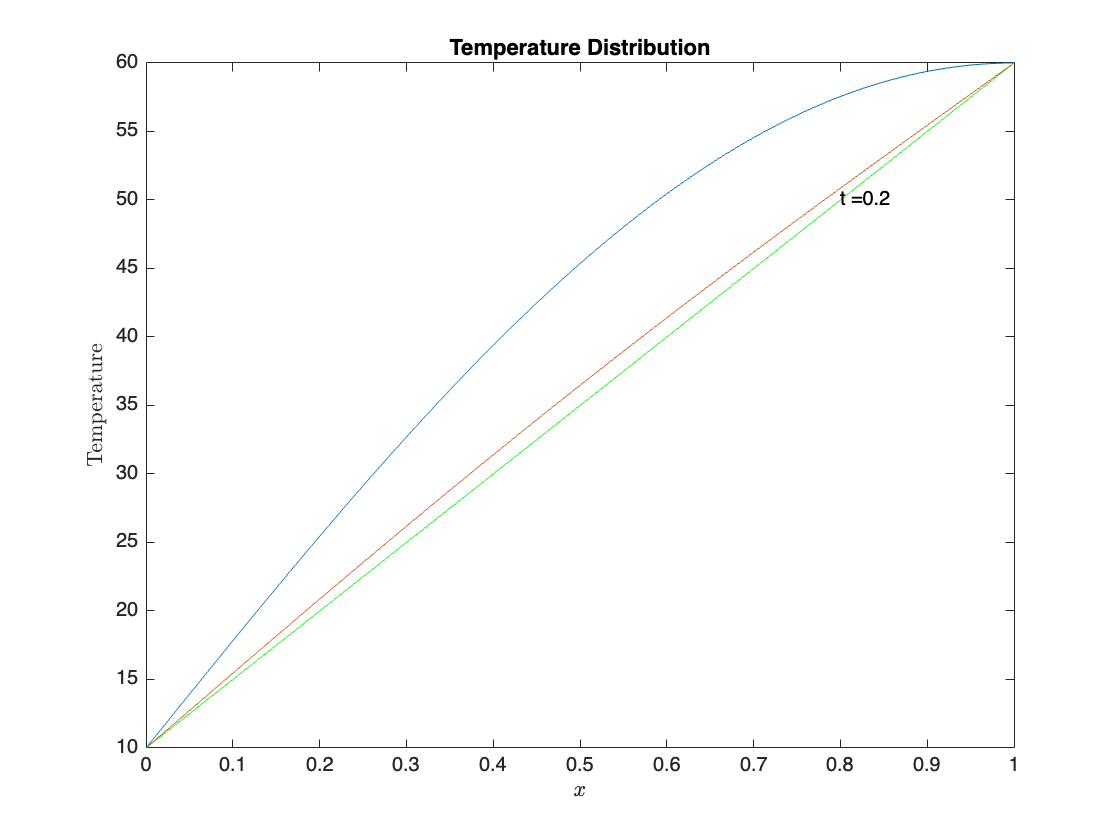

Q = zeros(numNod,1);

%Boundary conditions (BC): Natural BC
Q(freeNodes) = 0; %Not necessary, since Q has been initalised to 0.

%Initial Conditions
u_t = u_ini(nodes);
um = u_t(freeNodes);

%Reamrk: note that that essential BC are the same for each t

%Reduced system
Q_t = Q(freeNodes) - K(freeNodes,fixedNodes)*u_t(fixedNodes);

%System of equtions
Am = M(freeNodes,freeNodes)+dt*alpha*K(freeNodes,freeNodes);
Bm = M(freeNodes,freeNodes)-dt*(1-alpha)*K(freeNodes,freeNodes);
Fm = dt*Q_t;

%Graphical output
figure()
plot(nodes, u_t); %plot the initial state of u_t at t = tini
title('Temperature Distribution')
xlabel('$x$', 'Interpreter','latex')
ylabel('Temperature','Interpreter','latex')
hold on
plot(nodes, uStat, 'g') %Plot stationary soluiton

%Iterate to find the nodal values of u at each time-tick
for t =tini+dt:dt:tfin
    um = Am\(Bm*um+Fm);
    %plot current curve
    ff = plot(nodes(freeNodes),um);
    tt = text(nodes(end)-0.2,50,['t =' num2str(t)]);
    drawnow;
    pause(0.2)
    delete(tt);
    delete(ff);
end
plot(nodes(freeNodes),um);
text(nodes(end)-0.2,50,['t =' num2str(t)]);
hold off

u_t(freeNodes) = um;
%Precission: compare the difference between the two solutions
errorTemp = norm(uStat-u_t, inf);
fprintf("error = ||uStat - u_t||_Inf = %e\n", errorTemp)

error = ||uStat - u_t||_Inf = 1.471520e+00
